# Cinematica Inversa Manipolatore RRR

Manipolatore RRR Planare

Un **manipolatore RRR** planare è un braccio robotico composto da tre giunti rotoidali i cui assi di rotazione sono tutti paralleli. Questo tipo di robot opera su un piano e possiede *3 Gradi di Libertà* (**DoF**).

Lo **spazio operativo** descrive la posa dell'organo terminale (*end-effector*). Per un manipolatore RRR planare, la posa è definita da due coordinate cartesiane $(P_x ,P_y )$ e un orientamento $\phi$ rispetto a un asse fisso. Lo spazio operativo ha quindi dimensione $m=3$ ed è descritto dal vettore:


$$\mathbf{r} = \begin{pmatrix} P_x \\ P_y \\ \phi \end{pmatrix}$$


Poiché il numero di gradi di libertà ($n=3$) è uguale alla dimensione dello spazio operativo ($m=3$), il manipolatore è in grado di controllare in modo indipendente sia la posizione che l'orientamento del suo end-effector. Questo gli permette di raggiungere (quasi) ogni posa desiderata all'interno del suo spazio di lavoro.

## Cinematica Diretta

Per risolvere il problema analiticamente, utilizziamo il *Symbolic Math Toolbox*. Si definiscono prima di tutto le variabili simboliche che rappresentano le costanti del sistema (l**e lunghezze dei bracci**) e le variabili (**gli angoli dei giunti** e la **posa desiderata**).

% l1, l2, l3 sono le lunghezze dei tre bracci del manipolatore.
syms l1 l2 l3 real;

% q1, q2, q3 sono gli angoli dei tre giunti rotoidali.
syms q1 q2 q3_calc real;

% px, py, phi rappresentano la posizione (x, y) e l'orientamento desiderati.
syms Px Py phi real;

% P_wx, P_wy rappresentano la posizione del polso
syms P_wx P_wy real;

La cinematica diretta calcola la posizione $(x,y)$ e l'orientamento $\phi$ dell'end-effector a partire dagli angoli di giunto $(q_1 ,q_2 ,q_3 )$ noti.

% Posizione Primo Giunto (Origine)
x0 = 0;
y0 = 0;
% Posizione Secondo Giunto (Z1)
x1 = x0 + l1 * cos(q1);
y1 = y0 + l1 * sin(q1);
% Posizione Terzo Giunto (Z2)
x2 = x1 + l2 * cos(q1 + q2);
y2 = y1 + l2 * sin(q1 + q2);
% Posizione End Effector (Z3)
px_calc = x2 + l3 * cos(q1 + q2 + q3_calc);
py_calc = y2 + l3 * sin(q1 + q2 + q3_calc);

fprintf('Equazioni Cinematica Diretta (Posizione):\n');

Equazioni Cinematica Diretta (Posizione):


fprintf('Px = %s\n', px_calc);

Px = l2*cos(q1 + q2) + l1*cos(q1) + l3*cos(q1 + q2 + q3_calc)


fprintf('Py = %s\n', py_calc);

Py = l2*sin(q1 + q2) + l1*sin(q1) + l3*sin(q1 + q2 + q3_calc)


L'orientamento dell'end-effector $\phi$ è dato dalla somma degli angoli dei giunti

% phi_calc per non confonderlo con phi
phi_calc = q1 + q2 + q3_calc;
fprintf('Phi = %s\n', phi_calc);

Phi = q1 + q2 + q3_calc


## Cinematica Inversa

La **cinematica inversa **si occupa di determinare il vettore degli angoli dei giunti $\mathbf{q}={\bigl\lbrack q_1 \;\;q_2 \;\;q_3 \bigr\rbrack }^T$ che permette all'end-effector di raggiungere una **posa desiderata**, data dal vettore $\mathbf{r}={\bigl\lbrack P_x \;\;P_y \;\;\phi \bigr\rbrack }^T$.

In altre parole, data una specifica posizione ($P_x ,P_y$) e un orientamento $\phi$ nello spazio operativo, l'obiettivo è trovare la configurazione dei giunti che realizzi quella posa.

A differenza della cinematica diretta, che ammette sempre una soluzione unica, il problema inverso è più complesso e può avere:

**Nessuna Soluzione: **Se la posa è fuori dallo spazio di lavoro del robot

**Una O Più Soluzioni: **Diverse configurazioni dei giunti portano alla stessa posa dell'end-effector

La posizione finale desiderata dell'end-effector $(P_x ,P_y )$, è una funzione complessa e accoppiata di tutti e tre gli angoli $(q_1 ,q_2 ,q_3 )$. Tentare di risolvere direttamente il sistema sarebbe estremamente difficile. L'informazione cruciale che permette di sbloccare il problema è l'**orientamento finale**, cioè $\phi =q_1 +q_2 +q_3$ La conoscenza della **posizione** dell'**end-effector** $(x,y)$, del suo **orientamento **$\phi$ e della **lunghezza** dell'ultimo **braccio** $l_3$, permette di calcolare *univocamente* la posizione del giunto precedente (il "polso"), che chiameremo $(P_{wx} ,P_{wy} )$.

La posizione dell'end-effector $(P_x ,P_y )$ può essere vista come la somma vettoriale della posizione del polso, che chiameremo $P_w =(P_{wx} ,P_{wy} )$, e del vettore corrispondente al terzo braccio:


$$\begin{pmatrix} P_x \\ P_y \end{pmatrix} = \begin{pmatrix} P_{wx} \\ P_{wy} \end{pmatrix} + \mathbf{R}(\phi ) \begin{pmatrix} l_{3}\\ 0 \end{pmatrix}$$


Dove

Il vettore $\left(\begin{array}{c} l_3 \\ 0 \end{array}\right)$ rappresenta il vettore del link $3$ descritto nel suo sistema di riferimento locale, in cui l'asse $x$ è allineato con la direzione del link stesso

La matrice $\mathbf{R}(\phi )$ è le matrice di rotazione associata all'orientamento finale $\phi$. Isolando la posizione del polso $P_w$, si ottiene:


$$\begin{pmatrix} P_{wx} \\ P_{wy} \end{pmatrix} = \begin{pmatrix} P_x \\ P_y \end{pmatrix} - \mathbf{R}(\phi ) \begin{pmatrix} l_{3}\\ 0 \end{pmatrix} \qquad\longrightarrow\qquad \begin{pmatrix} P_{wx} \\ P_{wy} \end{pmatrix} = \begin{pmatrix} P_x \\ P_y \end{pmatrix} - \begin{pmatrix} \cos(\phi) & -\sin(\phi) \\ \sin(\phi) & \cos(\phi) \end{pmatrix} \begin{pmatrix} l_{3}\\ 0 \end{pmatrix}$$



$$\begin{pmatrix} P_{wx} \\ P_{wy} \end{pmatrix} = \begin{pmatrix} P_x \\ P_y \end{pmatrix} - \begin{pmatrix} l_{3}\cos(\phi)\\ l_{3}\sin(\phi) \end{pmatrix}$$


% Matrice R(phi)
R = [cos(q1 + q2 + q3_calc) -sin(q1 + q2 + q3_calc); sin(q1 + q2 + q3_calc) cos(q1 + q2 + q3_calc)];

fprintf('Matrice R:\n');

Matrice R:


disp(R);

$$\left(\begin{array}{cc} \cos\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right) & -\sin\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right)\\ \sin\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right) & \cos\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right) \end{array}\right)$$

% Vettore Link 3
l3_vec = [l3; 0];

% Vettore Posizione End Effector
Pe_calc = [px_calc; py_calc];
fprintf('Posizione End Effector:\n');

Posizione End Effector:


disp(Pe_calc);

$$\left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right) \end{array}\right)$$

% Posizione Polso
Pe = [Px; Py];
fprintf('Posizione Polso:\n');

Posizione Polso:


Pw_des = Pe - R * l3_vec;
disp(Pw_des);

$$\left(\begin{array}{c} \mathrm{Px}-l_{3}\,\cos\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right)\\ \mathrm{Py}-l_{3}\,\sin\left(q_{1}+q_{2}+q_{3,\mathrm{calc}}\right) \end{array}\right)$$

A questo punto, è fondamentale verificare la **raggiungibilità** del polso. La posizione $P_w$ deve trovarsi all'interno dello spazio di lavoro del "*sotto-manipolatore*" RR formato dai primi due bracci. La sua distanza dall'origine, $\sqrt{P_{wx}^2 +P_{wy}^2 }$, deve essere compresa tra l'estensione minima e massima dei bracci $l_1$ e $l_2$:

### 
$$|l_1 -l_2 |\le \sqrt{P_{wx}^2 +P_{wy}^2 }\le l_1 +l_2$$


Se questa **condizione** è **soddisfatta**, il punto $\biggl(\sqrt{P_{wx}^2 +P_{wy}^2 }\biggr)$ è all'interno dello spazio di lavoro del manipolatore RR. Questo garantisce che esista una soluzione reale per gli angoli $q_1$ e $q_2$. Matematicamente, questo assicura che il valore $\cos (q_2 )$ sarà compreso nell'intervallo $[-1,1]$

Se questa **condizione non** è **soddisfatta**, la posa desiderata è irraggiungibile. Cioè, non esiste alcuna configurazione reale degli angoli $q_1$ e $q_2$ che possa posizionare il polso in quel punto. Il valore di $\cos (q_2 )$, avrebbe modulo maggiore di $1$, rendendo impossibile trovare un angolo reale $q_2$

Si devono, quindi trovare $q_1$ e $q_2$ tali che il manipolatore RR posizioni il suo estremo in $P_w$

## Calcolo Valore $q_2$

Le equazioni di cinematica diretta per il polso sono:


$$\begin{array}{l} P_{wx} =l_1 \cos (q_1 )+l_2 \cos (q_1 +q_2 )\\ P_{wy} =l_1 \sin (q_1 )+l_2 \sin (q_1 +q_2 ) \end{array}$$


Per trovare $q_2$, si elevano al quadrato e si sommano le due equazioni.

Pw = Pe_calc - (R * l3_vec);
fprintf('P_{wx}^2 + P_{wy}^2 = \n');

P_{wx}^2 + P_{wy}^2 = 


quadSum = Pw(1)^2 + Pw(2)^2;
quadSum = simplify(quadSum);
disp(quadSum);

$${l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}$$

eq = P_wx^2 + P_wy^2 == quadSum;
cos_q2 = isolate(eq, cos(q2));
fprintf('Equazione Simbolica cos(q2):\n');

Equazione Simbolica cos(q2):


disp(cos_q2);

$$\cos\left(q_{2}\right)=\frac{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}-{l_{1}}^{2}-{l_{2}}^{2}}{2\,l_{1}\,l_{2}}$$

% Avendo i valori numerici
% Pw_calc = Pe_calc - (R * l3_vec);
% eq_calc = Pw_calc(1)^2 + Pw_calc(2)^2 == quadSum;
% sol_cos_q2_calc = isolate(eq_calc, cos(q2));
% disp(sol_cos_q2_calc);

Poiché $\sin^2 (q_2 )+\cos^2 (q_2 )=1$, si hanno due possibili soluzioni per $\sin (q_2 )$:

### 
$$\sin (q_2 )=\pm \sqrt{1-\cos (q_2 )^2 \;\;}$$


Queste due soluzioni corrispondono a due diverse configurazioni del braccio:

- **Gomito Alto** (Soluzione Positiva): Il gomito è sopra la linea che collega la base all'end-effector

- **Gomito Basso** (Soluzione Negativa): Il gomito è sotto la linea che collega la base all'end-effector

L'angolo $q_2$ si trova quindi con:

### 
$$q_2 =\textrm{atan2}(\sin (q_2 ),\cos (q_2 ))$$


cos_q2_val = rhs(cos_q2);
sin_q2_pos = sqrt(1 - cos_q2_val^2);
sin_q2_neg = -sqrt(1 - cos_q2_val^2);
q2_neg = atan2(sin_q2_neg, cos_q2_val);
q2_pos = atan2(sin_q2_pos, cos_q2_val);
fprintf('Valore q2 Per Valore Seno Negativo:\n');

Valore q2 Per Valore Seno Negativo:


disp(q2_neg);

$$\text{atan2}\left(-2\,\sqrt{1-\frac{{\left({P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}-{l_{1}}^{2}-{l_{2}}^{2}\right)}^{2}}{4\,{l_{1}}^{2}\,{l_{2}}^{2}}},\frac{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}-{l_{1}}^{2}-{l_{2}}^{2}}{l_{1}\,l_{2}}\right)$$

fprintf('Valore q2 Per Valore Seno Positivo:\n');

Valore q2 Per Valore Seno Positivo:


disp(q2_pos);

$$\text{atan2}\left(2\,\sqrt{1-\frac{{\left({P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}-{l_{1}}^{2}-{l_{2}}^{2}\right)}^{2}}{4\,{l_{1}}^{2}\,{l_{2}}^{2}}},\frac{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}-{l_{1}}^{2}-{l_{2}}^{2}}{l_{1}\,l_{2}}\right)$$

## Calcolo Valore $q_1$

Una volta noto $q_2$, si può risolvere per $q_1$. Il sistema di equazioni per la posizione del polso può essere riscritto come un sistema lineare nelle incognite $\cos (q_1 )$ e $\sin (q_1 )$

eq_Pwx = P_wx == Pw(1);
eq_Pwy = P_wy == Pw(2);

fprintf('Equazione P_wx:\n');

Equazione P_wx:


disp(eq_Pwx);

$$P_{\mathrm{wx}}=l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)$$

fprintf('Equazione P_wy:\n');

Equazione P_wy:


disp(eq_Pwy);

$$P_{\mathrm{wy}}=l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)$$

Ricordando che:


$$\begin{array}{l} \cos (\theta +\phi )=\cos (\theta )\cos (\phi )-\sin (\theta )\sin (\phi )\\ \sin (\theta +\phi )=\sin (\theta )\cos (\phi )+\cos (\theta )\sin (\phi ) \end{array}$$


Si può isolare $\cos (q_1 )$ nell'equazione precedente:

syms c1 s1 c2 s2 real;
% Expand serve per applicare le formule trigonometriche
eq_Pwx = expand(eq_Pwx);
eq_Pwy = expand(eq_Pwy);

% Si sostituiscono sin e cos con valori simbolici
eq_Pwx = subs(eq_Pwx, [cos(q1), sin(q1), cos(q2), sin(q2)], [c1, s1, c2, s2]);
eq_Pwy = subs(eq_Pwy, [cos(q1), sin(q1), cos(q2), sin(q2)], [c1, s1, c2, s2]);

% Si raccoglie sin e cos
eq_Pwx = collect(eq_Pwx, [c1,s1]);
eq_Pwy = collect(eq_Pwy, [c1,s1]);

% Si sostituiscono valori simbolici con sin e cos
eq_Pwx = subs(eq_Pwx, [c1, s1, c2, s2], [cos(q1), sin(q1), cos(q2), sin(q2)]);
eq_Pwy = subs(eq_Pwy, [c1, s1, c2, s2], [cos(q1), sin(q1), cos(q2), sin(q2)]);

fprintf('Sistema Lineare Per [cos(q1), sin(q1)]:\n');

Sistema Lineare Per [cos(q1), sin(q1)]:


disp(lhs(eq_Pwx) == rhs(eq_Pwx));

$$P_{\mathrm{wx}}=\cos\left(q_{1}\right)\,\left(l_{1}+l_{2}\,\cos\left(q_{2}\right)\right)-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)$$

disp(lhs(eq_Pwy) == rhs(eq_Pwy));

$$P_{\mathrm{wy}}=\sin\left(q_{1}\right)\,\left(l_{1}+l_{2}\,\cos\left(q_{2}\right)\right)+l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)$$

Il sistema precedente può essere scritto in forma matriciale


$$\left(\begin{array}{c} P_{wx} \\ P_{wy} \end{array}\right)=\left(\begin{array}{cc} l_1 +l_2 \cos(q_2 ) & -l_2 \sin (q_2 )\\ l_2 \sin (q_2 ) & l_1 +l_2 \cos(q_2 ) \end{array}\right)\left(\begin{array}{c} \cos q_1 \\ \sin q_1 \end{array}\right)$$


% Matrice Dei Coefficienti
A = [ l1 + l2*cos(q2),  -l2*sin(q2);
    l2*sin(q2),       l1 + l2*cos(q2) ];

% Vettore Dei Termini Noti
b = [P_wx; P_wy];

% 3. Definire il vettore delle incognite (per riferimento)
vars = [c1; s1];

fprintf('Matrice Coefficienti A:\n');

Matrice Coefficienti A:


disp(A);

$$\left(\begin{array}{cc} l_{1}+l_{2}\,\cos\left(q_{2}\right) & -l_{2}\,\sin\left(q_{2}\right)\\ l_{2}\,\sin\left(q_{2}\right) & l_{1}+l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

fprintf('Vettore Termini Noti b:\n');

Vettore Termini Noti b:


disp(b);

$$\left(\begin{array}{c} P_{\mathrm{wx}}\\ P_{\mathrm{wy}} \end{array}\right)$$

fprintf('Determinante Matrice Coefficienti:\n');

Determinante Matrice Coefficienti:


det_A = simplify(det(A));
disp(det_A);

$${l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}$$

Si nota che il determinante è esattamente uguale a $P_{wx}^2 +P_{wy}^2 =l_1^2 +l_2^2 +2l_1 l_2 \cos (q_2 )$ ovvero il quadrato della distanza del polso dall'origine. Nel caso in cui $P_{wx}^2 +P_{wy}^2 =0$, il che implica che il polso si trovi esattamente nell'origine $(0,0)$, si ha una singolarità cinematica e non è possibile determinare univocamente $q_1$ in quanto la matrice $A$ non è invertibile.

Una configurazione singolare rappresenta una condizione in cui il manipolatore perde uno o più gradi di libertà nel suo spazio operativo. Anche se possiede 3 giunti, in una singolarità non può muovere istantaneamente il suo end-effector in 3 direzioni indipendenti. Il manipolatore RRR planare, ha due tipi di singolarità:

- **Singolarità Di Confine:** Si verifica quando i primi due bracci sono completamente estesi ($q_2 =0$) o completamente ripiegati ($q_2 =\pi$). In questa configurazione i due link sono allineati. Qualsiasi movimento dei giunti $q_1$ e $q_2$ può produrre uno spostamento del polso solo in direzione tangenziale, ma non in quella radiale. Il manipolatore perde la capacità di "allungarsi" o "accorciarsi".

- **Singolarità Interne:** Si verificano quando la base, il secondo e il terzo giunto sono allineati. Questo accade proprio quando $q_2 =0$ o $q_2 =\pi$. In queste configurazioni, i movimenti di $q_1$ e $q_2$ generano spostamenti dell'end-effector che non sono più linearmente indipendenti, portando a una perdita di manovrabilità.

Operare in prossimità di una singolarità è problematico, infatti richiede velocità di giunto molto elevate per produrre un movimento dell'end-effector, con rischi per la struttura e gli attuatori. Pertanto, la pianificazione delle traiettorie deve sempre tenere conto di queste configurazioni e, se possibile, evitarle.

Nel caso in cui $\det \bigl\lbrack A(q_2 )\bigr\rbrack =0$ si ha una singolarità cinematica e non è possibile determinare $q_1$ in quanto $A(q_2 )$ non è invertibile. Nel caso in cui $\det\bigl\lbrack A(q_2 )\bigr\rbrack \not= 0$ si ha che


$${\left(\begin{array}{cc} l_1 +l_2 \cos(q_2 ) & -l_2 \sin (q_2 )\\ l_2 \sin (q_2 ) & l_1 +l_2 \cos(q_2 ) \end{array}\right)}^{-1} ~~\left(\begin{array}{c} P_{wx} \\ P_{wy} \end{array}\right)=\left(\begin{array}{c} \cos q_1 \\ \sin q_1 \end{array}\right)$$


sol_vec = A \ b;
sol_vec = simplify(sol_vec);

sol_cosq1 = sol_vec(1);
sol_sinq1 = sol_vec(2);

fprintf('Soluzione Di cos(q1):\n');

Soluzione Di cos(q1):


disp(sol_cosq1);

$$\frac{P_{\mathrm{wx}}\,l_{1}+P_{\mathrm{wy}}\,l_{2}\,\sin\left(q_{2}\right)+P_{\mathrm{wx}}\,l_{2}\,\cos\left(q_{2}\right)}{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}$$

fprintf('Soluzione Di sin(q1):\n');

Soluzione Di sin(q1):


disp(sol_sinq1);

$$\frac{P_{\mathrm{wy}}\,l_{1}-P_{\mathrm{wx}}\,l_{2}\,\sin\left(q_{2}\right)+P_{\mathrm{wy}}\,l_{2}\,\cos\left(q_{2}\right)}{{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}}$$

Ricordando che $P_{wx}^2 +P_{wy}^2 =l_1^2 +l_2^2 +2l_1 l_2 \cos (q_2 )$, andando a sostituire si avrà che

% GOMITO ALTO
cosq1_final = subs(sol_cosq1, l1^2 + 2*cos(q2)*l1*l2 + l2^2, P_wx^2 + P_wy^2);
fprintf('Valore Finale Di cos(q1):\n');

Valore Finale Di cos(q1):


disp(cosq1_final);

$$\frac{P_{\mathrm{wx}}\,l_{1}+P_{\mathrm{wy}}\,l_{2}\,\sin\left(q_{2}\right)+P_{\mathrm{wx}}\,l_{2}\,\cos\left(q_{2}\right)}{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}}$$

sinq1_final = subs(sol_sinq1, l1^2 + 2*cos(q2)*l1*l2 + l2^2, P_wx^2 + P_wy^2);
fprintf('Valore Finale Di sin(q1):\n');

Valore Finale Di sin(q1):


disp(sinq1_final);

$$\frac{P_{\mathrm{wy}}\,l_{1}-P_{\mathrm{wx}}\,l_{2}\,\sin\left(q_{2}\right)+P_{\mathrm{wy}}\,l_{2}\,\cos\left(q_{2}\right)}{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}}$$

L'angolo $q_1$ si trova quindi con:

### 
$$q_1 =\textrm{atan2}(\sin (q_1 ),\cos (q_1 ))$$


q1_neg = atan2(sinq1_final, cosq1_final);

fprintf('Valore q1 Calcolato:\n');

Valore q1 Calcolato:


disp(q1_neg);

$$\text{atan2}\left(\frac{P_{\mathrm{wy}}\,l_{1}-P_{\mathrm{wx}}\,l_{2}\,\sin\left(q_{2}\right)+P_{\mathrm{wy}}\,l_{2}\,\cos\left(q_{2}\right)}{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}},\frac{P_{\mathrm{wx}}\,l_{1}+P_{\mathrm{wy}}\,l_{2}\,\sin\left(q_{2}\right)+P_{\mathrm{wx}}\,l_{2}\,\cos\left(q_{2}\right)}{{P_{\mathrm{wx}}}^{2}+{P_{\mathrm{wy}}}^{2}}\right)$$

## Calcolo Valore $q_3$

A questo punto, avendo ricavato $q_1$ e $q_2$ l'angolo $q_3$ è ricavabile da

### 
$$\phi =q_1 +q_2 +q_3 \longrightarrow q_3 =\phi -q_1 -q_2$$


% Si calcola q3 con valore di q2 calcolato con valore positivo di sin(q2)
q3_calc_1 = phi - atan2(sinq1_final, cosq1_final) - atan2(sin_q2_pos, cos_q2_val);


% Si calcola q3 con valore di q2 calcolato con valore negativo di sin(q2)
q3_calc_2 = phi - atan2(sinq1_final, cosq1_final) - atan2(sin_q2_neg, cos_q2_val);

Se la posa desiderata $(P_x ,P_y ,\phi )$ è all'interno dello spazio di lavoro del manipolatore, il problema di cinematica inversa per un robot RRR planare **ammette** generalmente **due soluzioni distinte**. Queste due soluzioni corrispondono alle configurazioni di "*Gomito Alto*" e "*Gomito Basso*" e possono essere calcolate analiticamente seguendo la procedura di disaccoppiamento. La scelta tra le due soluzioni dipende da criteri aggiuntivi, come evitare ostacoli, minimizzare il movimento dei giunti o rimanere lontani dalle singolarità.

### 1. Soluzione Gomito Alto

- Si sceglie il valore positivo per il seno di $q_2$.

- Si calcola $q_{2,\text{Alto}}$ tramite l'arcotangente a quattro quadranti.

- Si utilizzano $\cos(q_{2,\text{Alto}})$ e $\sin(q_{2,\text{Alto}})$ per calcolare i valori $\cos(q_1)$ e $\sin(q_1)$.

- Si calcola $q_{1,\text{Alto}}$ tramite l'arcotangente a quattro quadranti.

- Infine, si calcola $q_{3,\text{Alto}}$ come $\phi - q_{1,\text{Alto}} - q_{2,\text{Alto}}$.

- **La prima terna di soluzioni è**: [ \mathbf{q}*{\text{Alto}} = \begin{pmatrix} q*{1,\text{Alto}} & q_{2,\text{Alto}} & q_{3,\text{Alto}} \end{pmatrix}^T ]

### 2. Soluzione Gomito Basso

- Si sceglie il valore negativo per il seno di $q_2$.

- Si calcola $q_{2,\text{Basso}}$ tramite l'arcotangente a quattro quadranti.

- Si utilizzano $\cos(q_{2,\text{Basso}})$ e $\sin(q_{2,\text{Basso}})$ per calcolare i valori $\cos(q_1)$ e $\sin(q_1)$.

- Si calcola $q_{1,\text{Basso}}$ tramite l'arcotangente a quattro quadranti.

- Infine, si calcola $q_{3,\text{Basso}}$ come $\phi - q_{1,\text{Basso}} - q_{2,\text{Basso}}$.

- **La seconda terna di soluzioni è**: [ \mathbf{q}*{\text{Basso}} = \begin{pmatrix} q*{1,\text{Basso}} & q_{2,\text{Basso}} & q_{3,\text{Basso}} \end{pmatrix}^T ]

## Spazio Operativo

Lo studio dello spazio operativo di un manipolatore è fondamentale per comprenderne le capacità e i limiti. Questo spazio viene suddiviso in due categorie principali: il Workspace Primario, che definisce l'area raggiungibile, e il Workspace Secondario, che caratterizza la destrezza del manipolatore.

Il **Workspace Primario** (o ***Spazio Operativo Primario***) $WS_1$ (Spazio Raggiungibile) è l'insieme di tutti i punti che l'organo terminale (end-effector) del manipolatore può raggiungere con almeno un orientamento possibile. In altre parole, se un punto target si trova all'interno di questo spazio, $P\in WS_1$, esiste almeno una configurazione di giunti che permette al manipolatore di raggiungerlo. Al contrario, se un punto si trova al di fuori di $WS_1$, il suo raggiungimento è impossibile e il problema cinematico non ammette soluzioni.

Il **Workspace Secondario** (o ***Spazio Operativo Secondario***) $WS_2$ (Spazio di Destrezza) è un sottoinsieme del workspace primario. Esso rappresenta l'insieme dei punti che l'end-effector può raggiungere con un numero molteplice di orientamenti, idealmente con qualsiasi orientamento possibile. Se un punto appartiene allo spazio secondario, $P\in WS_2$, significa che per quel punto esistono molteplici soluzioni cinematiche, garantendo una maggiore flessibilità nel completamento del task.

## Caso 1: Manipolatore con "Buco" Centrale

Si analizza il caso in cui la geometria del manipolatore non consente di raggiungere l'origine degli assi. Questa situazione si verifica quando il terzo braccio ($l_3$) è troppo corto per raggiungere l'origine dal punto più vicino a cui il polso (il giunto tra il secondo e il terzo braccio) può posizionarsi. Di conseguenza, lo spazio di lavoro presenterà un'area vuota al suo centro.

Lo ***Spazio Operativo Primario*** è definito dalla regione compresa tra due circonferenze concentriche. Il raggio massimo di questa regione, $R_{max}$, corrisponde alla massima estensione del manipolatore, ottenuta quando tutti e tre i bracci sono allineati e puntano verso l'esterno. La distanza minima, $R_{min}$, si ha invece quando il polso si trova alla sua minima distanza dall'origine ($|l_1 -l_2 |$) e il terzo braccio è orientato in direzione opposta, verso l'origine.

Analiticamente, un punto $P$ appartiene allo spazio primario se la sua distanza dall'origine $d=\sqrt{x^2 +y^2 }$, soddisfa la seguente relazione:

### 
$$||l_1 -l_2 |-l_3 |\le d\le l_1 +l_2 +l_3$$


% Lunghezze dei bracci del manipolatore RRR.
l1 = 10;
l2 = 4;
l3 = 2;

% Calcolo Raggio Esterno: Massima Estensione
R_max = l1 + l2 + l3;

% Calcolo Raggio Interno: Minima Distanza Raggiungibile
R_min = abs(l1 - l2) - l3;

fprintf('Spazio Primario - Raggio Interno (R_min): %.2f\n', R_min);

Spazio Primario - Raggio Interno (R_min): 4.00


fprintf('Spazio Primario - Raggio Esterno (R_max): %.2f\n', R_max);

Spazio Primario - Raggio Esterno (R_max): 16.00


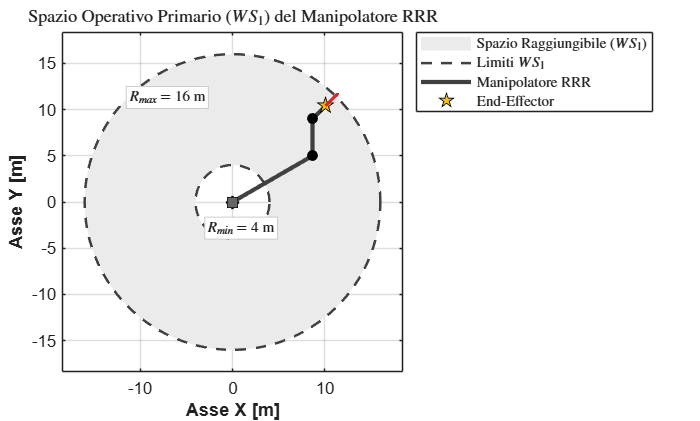

% --- Figura 1: Spazio Operativo Primario (WS1) ---
theta = linspace(0, 2*pi, 300);
x_ext = R_max * cos(theta);  y_ext = R_max * sin(theta);
x_in  = R_min * cos(theta);  y_in  = R_min * sin(theta);

col_link = [0.25, 0.25, 0.25];
col_red  = [0.85, 0.15, 0.15];
col_blue = [0.15, 0.35, 0.85];

figure('Name', 'Spazio Operativo Primario (WS1)', 'Color', 'w');
hold on; grid on; box on; axis equal;
xlabel('Asse X [m]', 'FontWeight', 'bold');
ylabel('Asse Y [m]', 'FontWeight', 'bold');

% Corona circolare WS1 e bordi limite
h_ws1 = fill([x_ext, fliplr(x_in)], [y_ext, fliplr(y_in)], [0.92, 0.92, 0.92], ...
    'EdgeColor', 'none', 'DisplayName', 'Spazio Raggiungibile ($WS_1$)');
h_lim = plot(x_ext, y_ext, '--', 'Color', col_link, 'LineWidth', 1.5, 'DisplayName', 'Limiti $WS_1$');
plot(x_in, y_in, '--', 'Color', col_link, 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Origine Assi
plot(0, 0, 'k+', 'MarkerSize', 8, 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Configurazione d'esempio del Manipolatore RRR in WS1
q_ex1 = [pi/6, pi/3, -pi/4];
p0 = [0, 0];
p1 = p0 + [l1*cos(q_ex1(1)), l1*sin(q_ex1(1))];
p2 = p1 + [l2*cos(q_ex1(1)+q_ex1(2)), l2*sin(q_ex1(1)+q_ex1(2))];
p3 = p2 + [l3*cos(sum(q_ex1)), l3*sin(sum(q_ex1))];
pts_arm1 = [p0; p1; p2; p3];

h_arm = plot(pts_arm1(:,1), pts_arm1(:,2), '-', 'Color', col_link, 'LineWidth', 2.5, ...
    'DisplayName', 'Manipolatore RRR');
plot(pts_arm1(2:3,1), pts_arm1(2:3,2), 'o', 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
plot(p0(1), p0(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', [0.4, 0.4, 0.4], 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
h_ee = plot(p3(1), p3(2), 'p', 'MarkerSize', 10, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'DisplayName', 'End-Effector');
quiver(p3(1), p3(2), 1.8*cos(sum(q_ex1)), 1.8*sin(sum(q_ex1)), 0, ...
    'Color', col_red, 'LineWidth', 1.8, 'MaxHeadSize', 0.6, 'HandleVisibility', 'off');

% Annotazioni Raggi Limite (posizionate nel II/III quadrante, lontano dal braccio)
ang_in = -3*pi/4;  ang_out = 3*pi/4;
text(R_min*cos(ang_in), R_min*sin(ang_in), sprintf('$R_{min} = %.0f$ m', R_min), ...
    'Interpreter', 'latex', 'FontSize', 9, 'FontWeight', 'bold', ...
    'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);
text(R_max*cos(ang_out), R_max*sin(ang_out), sprintf('$R_{max} = %.0f$ m', R_max), ...
    'Interpreter', 'latex', 'FontSize', 9, 'FontWeight', 'bold', ...
    'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);

title('Spazio Operativo Primario ($WS_1$) del Manipolatore RRR', ...
    'Interpreter', 'latex', 'FontSize', 11, 'FontWeight', 'bold');
legend([h_ws1, h_lim, h_arm, h_ee], 'Interpreter', 'latex', 'Location', 'bestoutside');
lim = R_max * 1.15;
xlim([-lim, lim]); ylim([-lim, lim]);
hold off;

Lo ***Spazio Operativo Secondario***, è quel sottoinsieme dello spazio primario dove l'end-effector può non solo raggiungere un punto, ma può farlo assumendo qualsiasi orientamento. La capacità di orientarsi liberamente è cruciale in molte applicazioni robotiche.

La condizione affinché un punto $P$ appartenga a questo spazio privilegiato è che il cerchio di raggio $l_3$ centrato in $P$ sia interamente contenuto nello spazio di lavoro del polso. Questo garantisce che, per qualsiasi rotazione del terzo braccio, il polso rimanga sempre in una posizione raggiungibile. Analiticamente, la distanza $d$ di un punto $P$ dall'origine deve soddisfare la seguente disuguaglianza:

### 
$$|l_1 -l_2 |+l_3 \le d\le l_1 +l_2 -l_3$$


Questa condizione ha senso solo se il raggio minimo è minore o uguale al raggio massimo, ovvero se $|l_1 -l_2 |+l_3 \le l_1 +l_2-l_3$, che si semplifica in $l_3 \le l_2$ (assumendo $l_1 \ge l_2$). Se questa condizione non è rispettata, lo spazio di destrezza è vuoto.

Nel caso specifico $l_1 =10,l_2 =4,l_3 =2$, dato che la condizione $l_3 \le l_2$ ($2\le 4$) è soddisfatta, lo spazio di destrezza esiste. I suoi limiti sono:

- Raggio Minimo di $WS_2 :\;|10-4|+2=8$

- Raggio Massimo di $WS_2 :\;10+4-2=12$

Lo Spazio Operativo Secondario è quindi l'anello definito dalla condizione $8\le d\le 12$. Solo all'interno di questa corona circolare il manipolatore gode della massima destrezza, potendo orientare il suo organo terminale in qualsiasi direzione. Nelle restanti aree dello spazio primario, gli orientamenti possibili sono limitati.

% Lo spazio di destrezza esiste solo se il suo raggio massimo è
% maggiore o uguale al suo raggio minimo.
R_min_ws2 = 0;
R_max_ws2 = 0;
if (l1 + l2 - l3) >= (abs(l1-l2) + l3)
    R_min_ws2 = abs(l1 - l2) + l3;
    R_max_ws2 = (l1 + l2) - l3;
end

fprintf('Spazio Secondario - Raggio Interno (R_min_ws2): %.2f\n', R_min_ws2);

Spazio Secondario - Raggio Interno (R_min_ws2): 8.00


fprintf('Spazio Secondario - Raggio Esterno (R_max_ws2): %.2f\n', R_max_ws2);

Spazio Secondario - Raggio Esterno (R_max_ws2): 12.00


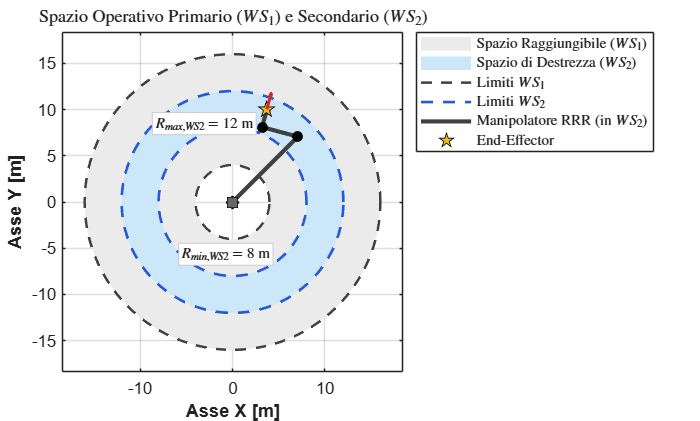

% --- Figura 2: Spazio Operativo Primario (WS1) e Secondario (WS2) ---
figure('Name', 'Spazio Operativo Primario e Secondario', 'Color', 'w');
hold on; grid on; box on; axis equal;
xlabel('Asse X [m]', 'FontWeight', 'bold');
ylabel('Asse Y [m]', 'FontWeight', 'bold');

% Coordinate dei cerchi per WS1 (Spazio Primario) e WS2 (Spazio Secondario)
theta = linspace(0, 2*pi, 300);
x_ext_ws1 = R_max * cos(theta);      y_ext_ws1 = R_max * sin(theta);
x_int_ws1 = R_min * cos(theta);      y_int_ws1 = R_min * sin(theta);
x_ext_ws2 = R_max_ws2 * cos(theta);  y_ext_ws2 = R_max_ws2 * sin(theta);
x_int_ws2 = R_min_ws2 * cos(theta);  y_int_ws2 = R_min_ws2 * sin(theta);

% Corona WS1 (Raggiungibile) e Corona WS2 (Destrezza)
h_ws1 = fill([x_ext_ws1, fliplr(x_int_ws1)], [y_ext_ws1, fliplr(y_int_ws1)], [0.92, 0.92, 0.92], ...
    'EdgeColor', 'none', 'DisplayName', 'Spazio Raggiungibile ($WS_1$)');
h_ws2 = fill([x_ext_ws2, fliplr(x_int_ws2)], [y_ext_ws2, fliplr(y_int_ws2)], [0.80, 0.90, 0.98], ...
    'EdgeColor', 'none', 'DisplayName', 'Spazio di Destrezza ($WS_2$)');

% Bordi Limite Tratteggiati
h_lim_ws1 = plot(x_ext_ws1, y_ext_ws1, '--', 'Color', col_link, 'LineWidth', 1.5, 'DisplayName', 'Limiti $WS_1$');
plot(x_int_ws1, y_int_ws1, '--', 'Color', col_link, 'LineWidth', 1.5, 'HandleVisibility', 'off');
h_lim_ws2 = plot(x_ext_ws2, y_ext_ws2, '--', 'Color', col_blue, 'LineWidth', 1.6, 'DisplayName', 'Limiti $WS_2$');
plot(x_int_ws2, y_int_ws2, '--', 'Color', col_blue, 'LineWidth', 1.6, 'HandleVisibility', 'off');

% Origine Assi
plot(0, 0, 'k+', 'MarkerSize', 8, 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Configurazione d'esempio del Manipolatore RRR dentro WS2 (Destrezza)
q_ex2 = [pi/4, 2*pi/3, -pi/2];
p0 = [0, 0];
p1 = p0 + [l1*cos(q_ex2(1)), l1*sin(q_ex2(1))];
p2 = p1 + [l2*cos(q_ex2(1)+q_ex2(2)), l2*sin(q_ex2(1)+q_ex2(2))];
p3 = p2 + [l3*cos(sum(q_ex2)), l3*sin(sum(q_ex2))];
pts_arm2 = [p0; p1; p2; p3];

h_arm = plot(pts_arm2(:,1), pts_arm2(:,2), '-', 'Color', col_link, 'LineWidth', 2.5, ...
    'DisplayName', 'Manipolatore RRR (in $WS_2$)');
plot(pts_arm2(2:3,1), pts_arm2(2:3,2), 'o', 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
plot(p0(1), p0(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', [0.4, 0.4, 0.4], 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');
h_ee = plot(p3(1), p3(2), 'p', 'MarkerSize', 10, ...
    'MarkerFaceColor', [0.95, 0.75, 0.10], 'MarkerEdgeColor', 'k', 'DisplayName', 'End-Effector');
quiver(p3(1), p3(2), 1.8*cos(sum(q_ex2)), 1.8*sin(sum(q_ex2)), 0, ...
    'Color', col_red, 'LineWidth', 1.8, 'MaxHeadSize', 0.6, 'HandleVisibility', 'off');

% Annotazioni Raggi WS2 (posizionate nel II/III quadrante, lontano dal braccio)
ang_ws2_in = -3*pi/4;  ang_ws2_out = 3*pi/4;
text(R_min_ws2*cos(ang_ws2_in), R_min_ws2*sin(ang_ws2_in), sprintf('$R_{min,WS2} = %.0f$ m', R_min_ws2), ...
    'Interpreter', 'latex', 'FontSize', 9, 'FontWeight', 'bold', ...
    'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);
text(R_max_ws2*cos(ang_ws2_out), R_max_ws2*sin(ang_ws2_out), sprintf('$R_{max,WS2} = %.0f$ m', R_max_ws2), ...
    'Interpreter', 'latex', 'FontSize', 9, 'FontWeight', 'bold', ...
    'BackgroundColor', [1 1 1], 'EdgeColor', [0.8 0.8 0.8], 'Margin', 1);

title('Spazio Operativo Primario ($WS_1$) e Secondario ($WS_2$)', ...
    'Interpreter', 'latex', 'FontSize', 11, 'FontWeight', 'bold');
legend([h_ws1, h_ws2, h_lim_ws1, h_lim_ws2, h_arm, h_ee], 'Interpreter', 'latex', 'Location', 'bestoutside');
lim = R_max * 1.15;
xlim([-lim, lim]); ylim([-lim, lim]);
hold off;